# Transfer Learning Using AlexNet

此例说明使用微调预训练的 AlexNet 卷积神经网络以对新的图像集合执行分类。

AlexNet 已基于超过一百万个图像进行训练，可以将图像分为 1000 个对象类别（例如键盘、咖啡杯、铅笔和多种动物）。该网络已基于大量图像学习了丰富的特征表示。网络以图像作为输入，然后输出图像中对象的标签以及每个对象类别的概率。

深度学习应用中常常用到迁移学习。采用预训练的网络，基于它学习新任务。与使用随机初始化的权重从头训练网络相比，通过迁移学习微调网络要更快更简单。可以使用较少数量的训练图像快速地将已学习的特征迁移到新任务

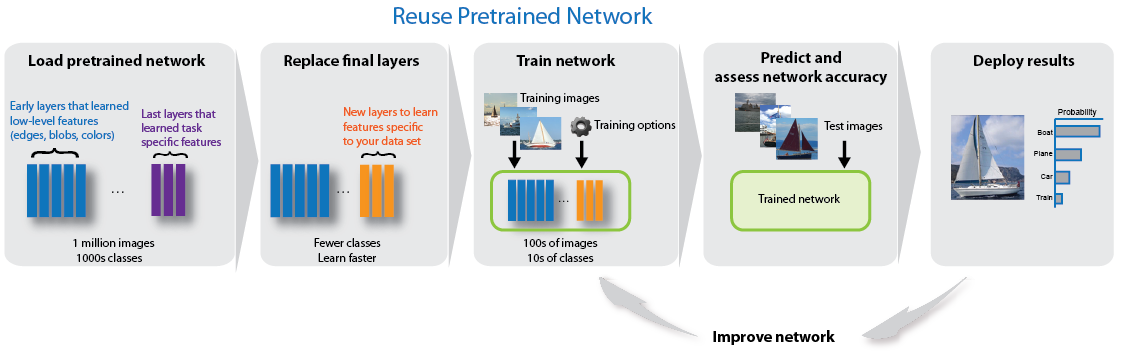

## **加载数据**

首先将源数据中的掩模图像转化为jpg然后根据临床数据中的淋巴结转移的阴阳划分为两个文件夹，然后加载图像作为图像数据存储。`imageDatastore`根据文件夹名称自动标记图像，并将数据存储为`ImageDatastore`对象。通过图像数据存储可以存储大图像数据，包括无法放入内存的数据，并在卷积神经网络的训练过程中高效分批读取图像。

unzip('BQuanBuShuJuYanMo.zip');
imds = imageDatastore('BQuanBuShuJuYanMo', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

将数据划分为训练数据集和验证数据集。将 70% 的图像用于训练，30% 的图像用于验证。`splitEachLabel` 将 `images`数据存储拆分为两个新的数据存储

[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7,'randomized');

显示一些示例图像

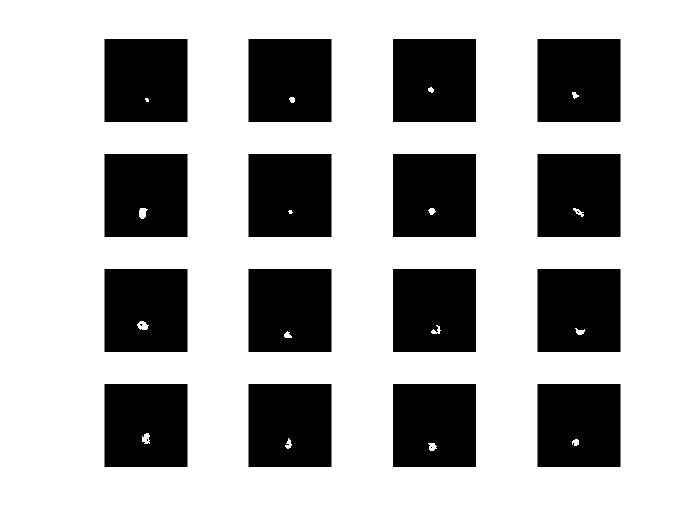

numTrainImages = numel(imdsTrain.Labels);
idx = randperm(numTrainImages,16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(imdsTrain,idx(i));
    imshow(I)
end

## **加载预训练网络**

加载预训练的 AlexNet 神经网络。如果未安装 Deep Learning Toolbox™ Model*for AlexNet Network*，则软件会提供下载链接。AlexNet 已基于超过一百万个图像进行训练，可以将图像分为 1000 个对象类别（例如键盘、鼠标、铅笔和多种动物）。因此，该模型已基于大量图像学习了丰富的特征表示

net = alexnet;

使用`analyzeNetwork`可以交互可视方式呈现网络架构以及有关网络层的详细信息。

analyzeNetwork(net)

第一层（图像输入层）需要大小为 227×227×3 的输入图像，其中 3 是颜色通道数。

inputSize = net.Layers(1).InputSize

inputSize =    227   227     3


## **替换最终层**

预训练网络`net`的最后三层针对 1000 个类进行配置。必须针对新分类问题微调这三个层。从预训练网络中提取除最后三层之外的所有层

layersTransfer = net.Layers(1:end-3);

通过将最后三层替换为全连接层、softmax 层和分类输出层，将层迁移到新分类任务。根据新数据指定新的全连接层的选项。将全连接层设置为大小与新数据中的类数相同

numClasses = numel(categories(imdsTrain.Labels))

numClasses = 107

layers = [
    layersTransfer
    fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
    softmaxLayer
    classificationLayer];

## **训练网络**

网络要求输入图像的大小为 227×227×3，但图像数据存储中的图像具有不同大小。使用增强的图像数据存储可自动调整训练图像的大小。

pixelRange = [-30 30];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter);

要在不执行进一步数据增强的情况下自动调整验证图像的大小，使用增强的图像数据存储，而不指定任何其他预处理操作。

augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

指定训练选项。对于迁移学习，保留预训练网络的较浅层中的特征（迁移的层权重）。在上一步中，增大了全连接层的学习率因子，以加快新的最终层中的学习速度。这种学习率设置组合只会加快新层中的学习速度，对于其他层则会减慢学习速度。执行迁移学习时，所需的训练轮数相对较少。一轮训练是对整个训练数据集的一个完整训练周期。指定小批量大小和验证数据。软件在训练过程中每`ValidationFrequency`次迭代验证一次网络。

options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress');

训练由迁移层和新层组成的网络。默认情况下，如果有 GPU 可用，`trainNetwork`就会使用 GPU（需要 Parallel Computing Toolbox™ 和具有 3.0 或更高计算能力的支持 CUDA® 的 GPU）。否则，将使用 CPU。您还可以使用`trainingOptions` 的 `'ExecutionEnvironment'`名称-值对组参数指定执行环境

netTransfer = trainNetwork(augimdsTrain,layers,options);

错误使用 trainNetwork (line 150)
The training images are of size 227x227x1 but the input layer expects images of size 227x227x3.

## **对验证图像进行分类**

使用经过微调的网络对验证图像进行分类。

[YPred,scores] = classify(netTransfer,augimdsValidation);

使用经过微调的网络对验证图像进行分类。

idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label));
end

计算针对验证集的分类准确度。准确度是网络预测正确的标签的比例

YValidation = imdsValidation.Labels;
accuracy = mean(YPred == YValidation)